clc; clear; close all;

# 2. (60%) Consider the concrete pier problem in HW1. 

% const
Ee = 2e7; % kN/m2
unit_weighs = 24; %kN/m3
t_bar = 20; % kN/m2

## (a) Construct the element stiffness matrix and element external force matrix that takes into consideration of linear variation of cross section.

% variable
syms x xe1 xe2

Ae = x + 1;

p = [1 x];

Me = [
    1 xe1;
    1 xe2;
];

Ne = simplify(p / Me);

Be = diff(Ne, x);

Ke = simplify(int(Be.' * Ae * Ee * Be, x, xe1, xe2));

Ke1 = subs(Ke, [xe1 xe2], [0, 1])

$$Ke1 = \left(\begin{array}{cc} 30000000 & -30000000\\ -30000000 & 30000000 \end{array}\right)$$

Ke2 = subs(Ke, [xe1 xe2], [1, 2])

$$Ke2 = \left(\begin{array}{cc} 50000000 & -50000000\\ -50000000 & 50000000 \end{array}\right)$$


b(x) = unit_weighs * (x + 1);

fe_omega = simplify(int(Ne.' * b(x), x, xe1, xe2));

fe_gamma = subs(Ne.' * Ae * t_bar, x, 0);

fe1 = subs(fe_omega + fe_gamma, [xe1 xe2], [0, 1])

$$fe1 = \left(\begin{array}{c} 36\\ 20 \end{array}\right)$$

fe2 = subs(fe_omega, [xe1 xe2], [1, 2])

$$fe2 = \left(\begin{array}{c} 28\\ 32 \end{array}\right)$$

## (b) Assemble these two elements to obtain the global stiffness matrix and global external force matrix. Compute the nodal displacements.

Kg = zeros(3);

for index = 1 : 2
    Kg([index, index + 1], [index, index + 1]) = Kg([index, index + 1], [index, index + 1]) + eval(['Ke' num2str(index)]);
end

Kg

Kg =     30000000   -30000000           0
   -30000000    80000000   -50000000
           0   -50000000    50000000



fg = zeros(3, 1);

for index = 1 : 2
    fg([index, index + 1], 1) = fg([index, index + 1], 1) + eval(['fe' num2str(index)]);
end

fg

fg =     36
    48
    32



dg = zeros(3, 1);

dg([1 2], 1) = Kg([1 2], [1 2]) \ fg([1 2], 1)

dg =    1.0e-05 *

    0.2880
    0.1680
         0



r = Kg * dg - fg;


## (c) Use MATLAB to plot a comparison of the FEM results with exact and classical linear approximation solutions obtained from HW1.

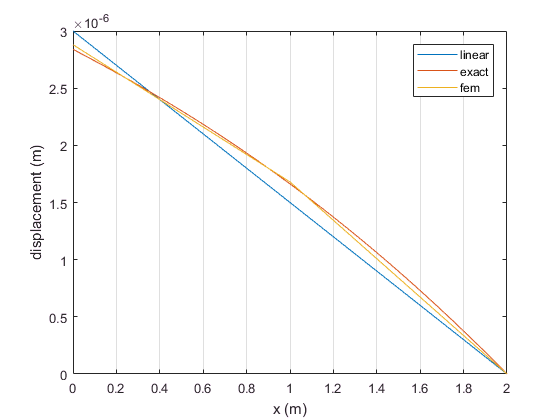

x1 = 0 : 0.01 : 2;

u_linear = 10^-7 * (30 - 15 * x1);

u_exact = (-6 * (x1 + 1).^2 - 8 * log(x1 + 1) + 54 + 8 * log(3)) / (2 * 10^7);

x2 = [0; 1; 2];

figure;
plot(x1, u_linear, x1, u_exact, x2, dg);
legend('linear', 'exact', 'fem');
xlabel('x (m)');
ylabel('displacement (m)');
set(gca, 'XGrid', 'on', 'YGrid', 'off');